%% build_SummaryTable.m
% Scan a folder of per-cell Excel files, extract metadata from filenames,
% read 1–3 rows based on condition keys, map values by header name,
% and write a single SummaryTable.xlsx to the same folder.

% ---------- User input ----------
inputFolder = '/Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/output_test';
% --------------------------------

% Output schema (exact order)
outVars = { ...
    'CellID','treatment','wpi','condition_filename','date','cellNumber', ...
    'Expter_Name', ...                                %%% <<< CHANGED (added column)
    'Expt_cond', ...
    'I_0_3','I_1','I_3','I_10','I_30','I_100','I_300','I_1000', ...
    'avgRundown_per_iteration','threshold','Rmax','pchipSlope' ...
};

outTypes = [ ...
    repmat({'string'},1,8), ...                      %%% <<< CHANGED (was 7 text cols; now 8 incl. Expter_Name)
    repmat({'double'},1,12) ...
];

% Prepare empty summary table with fixed schema
SummaryTable = table('Size',[0 numel(outVars)], ...
    'VariableTypes',outTypes,'VariableNames',outVars);

% Gather files (.xlsx and .xls)
files = [dir(fullfile(inputFolder,'*.xlsx')); dir(fullfile(inputFolder,'*.xls'))];
files = files(~[files.isdir]);  % safety

if isempty(files)
    fprintf('No .xlsx or .xls files found in: %s\n', inputFolder);
end

for k = 1:numel(files)
    fpath = fullfile(files(k).folder, files(k).name);
    [~, base, ~] = fileparts(fpath);

    % ---- Parse filename (split by underscores only) ----
    % Expected patterns (condition may include underscores/hyphens):
    % 1) treatment _ wpi _ condition _ date _ cellToken
    % 2) treatment _ wpi _ condition _ date _ cellToken _ Expter
    try
        meta = parseFilenameTokens(base); % no regexp for tokenization
    catch ME
        warning('Skipping file (bad filename format): %s\n  -> %s', files(k).name, ME.message);
        continue;
    end

    % Determine search keys (ordered aCSF -> GBZ -> NBQX_APV)
    keys = computeKeys(meta.condition_filename);

    fprintf('Processing: %s\n', files(k).name);

    % Try to read the first sheet
    T = [];
    try
        T = readtable(fpath, 'FileType','spreadsheet');
    catch ME
        warning('  Could not read file: %s\n  -> %s', files(k).name, ME.message);
        continue;
    end

    % Normalize header names for mapping (case/space-insensitive)
    varNames = string(T.Properties.VariableNames);
    normMap = buildHeaderIndex(varNames);  % containers.Map of normalizedName -> colIndex

    % Column A (first column) will be used for matching search keys
    colA = string(strtrim(T{:,1}));
    colA_lower = lower(colA);

    % For each key, append matches (all rows) or a single NaN row if none
    for qi = 1:numel(keys)
        key = keys(qi);
        mask = strcmp(colA_lower, lower(strtrim(key)));
        idx = find(mask);

        if isempty(idx)
            fprintf('  Key %-9s : NO match -> append NaNs\n', key);
            SummaryTable = [SummaryTable; buildOutRow(meta, key, T, [], normMap)]; %#ok<AGROW>
        else
            fprintf('  Key %-9s : %d match(es)\n', key, numel(idx));
            for ii = 1:numel(idx)
                SummaryTable = [SummaryTable; buildOutRow(meta, key, T, idx(ii), normMap)]; %#ok<AGROW>
            end
        end
    end
end

Processing: MMZ_2w_aCSF-GBZ-NBQX_APV_250101_cell2_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)


Processing: MMZ_2w_aCSF-GBZ-NBQX_APV_250827_cell7_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)


Processing: PBS_2w_aCSF-GBZ-NBQX_APV_250201_cell3_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)


Processing: PBS_2w_aCSF-GBZ-NBQX_APV_250827_cell7_HM.xlsx


  Key aCSF      : 1 match(es)
  Key GBZ       : 1 match(es)
  Key NBQX_APV  : 1 match(es)



% Write output
outFile = fullfile(inputFolder, 'SummaryTable.xlsx');
writetable(SummaryTable, outFile);
fprintf('Done. Wrote %d rows to %s\n', height(SummaryTable), outFile);

Done. Wrote 12 rows to /Users/hyou/Documents/OSN_Stim_MTCInputOutput_analysis_script/output_test/SummaryTable.xlsx




%% ----------------- Helper functions -----------------

function meta = parseFilenameTokens(base)
% Parse tokens from basename (no path/extension).
% Tokenization policy: split on '_' only.
% Supports two endings:
%   ... _ date _ cellN
%   ... _ date _ cellN _ Expter
    parts = split(string(base), '_');
    if numel(parts) < 5
        error('Expected at least 5 underscore-separated tokens.');
    end

    treatment = parts(1);
    wpi       = parts(2);

    %%% <<< CHANGED: allow optional trailing experimenter token
    % Detect whether the last token is a cell token or an experimenter.
    lastTok = parts(end);
    if startsWith(lower(lastTok), "cell") || ~isempty(regexp(lastTok, '^cell\d+$', 'once'))
        % No experimenter in filename
        expter    = "";                          % none
        cellToken = parts(end);
        dateStr   = parts(end-1);
        if numel(parts) == 5
            condition = parts(3);
        else
            condition = strjoin(parts(3:end-2), '_');
        end
    else
        % Has experimenter (e.g., ... _ cell2 _ HM)
        expter    = lastTok;
        cellToken = parts(end-1);
        dateStr   = parts(end-2);
        if numel(parts) == 6
            condition = parts(3);
        else
            condition = strjoin(parts(3:end-3), '_');
        end
    end
    %%% <<< end CHANGED

    % Extract numeric cell number from cellToken (e.g., "cell7" -> 7). If missing -> NaN.
    tok = regexp(cellToken, '\d+', 'match', 'once');  % allowed here (not for tokenization)
    if isempty(tok), cellNum = NaN; else, cellNum = str2double(tok); end

    % Preserve originals as strings (except numeric cellNumber)
    meta = struct();
    meta.CellID             = string(base);
    meta.treatment          = treatment;
    meta.wpi                = wpi;
    meta.condition_filename = condition;
    meta.date               = dateStr;
    meta.cellNumber         = cellNum;
    meta.Expter_Name        = string(expter);         %%% <<< CHANGED (store experimenter)
end

function keys = computeKeys(condition_filename)
% Build ordered list of keys based on condition in filename.
    c = lower(condition_filename);
    keys = string({'aCSF'});  % always
    if contains(c, 'gbz')
        keys(end+1) = "GBZ";
    end
    if contains(c, 'nbqx_apv')
        keys(end+1) = "NBQX_APV";
    end
end

function norm = normName(s)
% Normalize header names for robust matching (case- and space-insensitive).
    norm = lower(regexprep(strtrim(string(s)), '[^\w]|[ ]', ''));
end

function normMap = buildHeaderIndex(varNames)
% Build lookup of normalized variable names -> column index
    normMap = containers.Map('KeyType','char','ValueType','double');
    for i = 1:numel(varNames)
        key = char(normName(varNames(i)));
        if ~isKey(normMap, key)
            normMap(key) = i;
        end
    end
end

function rowT = buildOutRow(meta, key, T, rowIdx, normMap)
% Construct a one-row table in the required schema, pulling values by header name.
    outVars = { ...
        'CellID','treatment','wpi','condition_filename','date','cellNumber', ...
        'Expter_Name', ...                            %%% <<< CHANGED (added column)
        'Expt_cond', ...
        'I_0_3','I_1','I_3','I_10','I_30','I_100','I_300','I_1000', ...
        'avgRundown_per_iteration','threshold','Rmax','pchipSlope' ...
    };
    outTypes = [ ...
        repmat({'string'},1,8), ...                  %%% <<< CHANGED (text count updated)
        repmat({'double'},1,12) ...
    ];

    % Initialize with empties/NaNs
    rowT = table('Size',[1 numel(outVars)], ...
        'VariableTypes',outTypes,'VariableNames',outVars);

    % Fill metadata/text fields
    rowT.CellID             = meta.CellID;
    rowT.treatment          = meta.treatment;
    rowT.wpi                = meta.wpi;
    rowT.condition_filename = meta.condition_filename;
    rowT.date               = meta.date;
    rowT.cellNumber         = meta.cellNumber;
    rowT.Expter_Name        = meta.Expter_Name;      %%% <<< CHANGED (populate new column)
    rowT.Expt_cond          = string(key);

    % If no matching data row, leave numeric as NaN
    if isempty(rowIdx)
        return;
    end

    % Map source headers -> target names (one-to-one by name)
    targetNames = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000", ...
                   "avgRundown_per_iteration","threshold","Rmax","pchipSlope"];

    for t = 1:numel(targetNames)
        tgt = targetNames(t);
        srcKey = char(normName(tgt));
        if isKey(normMap, srcKey)
            col = normMap(srcKey);
            val = T{rowIdx, col};
            rowT.(tgt) = coerceDouble(val);
        else
            rowT.(tgt) = NaN;
        end
    end
end

function x = coerceDouble(val)
% Coerce a scalar/1x1 cell/char/string to double; non-numeric -> NaN.
    if iscell(val), val = val{1}; end
    if isnumeric(val) && isscalar(val)
        x = double(val); return;
    end
    if isstring(val) || ischar(val)
        tmp = str2double(strtrim(string(val)));
        x = tmp; if isnan(tmp), x = NaN; end
        return;
    end
    try
        x = double(val);
        if ~isscalar(x), x = NaN; end
    catch
        x = NaN;
    end
end


## Figure plotting

### Compare by treatment

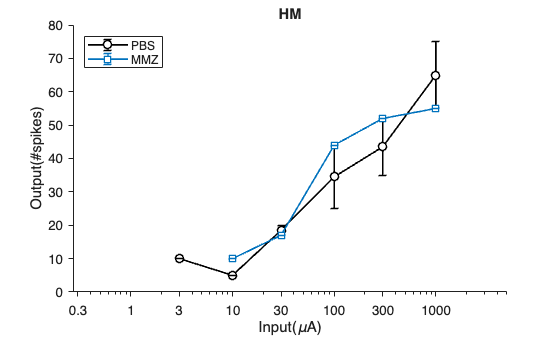

fname = 'SummaryTable.xlsx';   % adjust path if needed
T = readtable(fname, 'FileType','spreadsheet');

% --- Set up filters for grouping comparisons ----

% list out columns names needed for grouping
needCols = {'Expter_Name','wpi','Expt_cond'}; % =Preset=

% normalise column content into strings
for k = 1:numel(needCols)
    % check for matching columns, throws an error if missing
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    
    % convert column content from char to string and remove tailing spaces
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

% Filter: HM, 2w, aCSF =Preset, requires input
mask = strcmpi(T.Expter_Name, "HM") & ...
       strcmpi(T.wpi,         "2w") & ...
       strcmpi(T.Expt_cond,   "aCSF");

T_HM_2w_aCSF = T(mask,:);


% --- (1) check repeated CellID ---
ids = string(T_HM_2w_aCSF.CellID);
[u, ~, ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

% % --- (2) Cell count per treatment ---
T2 = T_HM_2w_aCSF;
T2.treatment = string(T2.treatment);
% CellCountTbl = groupcounts(string(T2.treatment));
% CellCountTbl.Properties.VariableNames = {'treatment','CellCount'};

% --- (3) column means / SD / SEM per treatment ---
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","pchipSlope"];
varsAll    = [varsSpikes varsParams];

% converting datatype into double
for v = varsAll
    x = T2.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end

    % Make sure it is a Nx1 vector, with N beling all values in x
    T2.(v) = reshape(x,[],1);
end

% Per treatment, calculate mean, SEM & SD for IO, threshold, Rmax & slope 
treats = unique(T2.treatment,'stable');
stats = struct();

% Looping through each treatment...
for i = 1:numel(treats)
    
    % Builds a logical mask selecting the rows in T2 
    % that belong to current treatment - treats(i)
    tr = treats(i);
    rows = (T2.treatment==tr);

    % indexing IO columns for current treatment
    Xspk = T2{rows, varsSpikes};
    % Column-wise calculation
    mSpk = mean(Xspk, 1, 'omitnan');
    sdSpk = std(Xspk, 0, 1, 'omitnan');
    nSpk  = sum(~isnan(Xspk), 1);
    semSpk = sdSpk ./ max(nSpk,1).^0.5;

    % indexing parameter columns...
    Xpar = T2{rows, varsParams};
    mPar = mean(Xpar, 1, 'omitnan');
    sdPar = std(Xpar, 0, 1, 'omitnan');
    nPar  = sum(~isnan(Xpar), 1);
    semPar = sdPar ./ max(nPar,1).^0.5;

    stats.(tr).meanSpikes = mSpk;
    stats.(tr).sdSpikes   = sdSpk;
    stats.(tr).semSpikes  = semSpk;
    stats.(tr).nSpikes    = nSpk;
    stats.(tr).meanPars   = mPar;
    stats.(tr).sdPars     = sdPar;
    stats.(tr).semPars    = semPar;
    stats.(tr).nPars      = nPar;
end

% --- (4) overlay line plot: mean ± SEM across intensities ---
xVals = [0.3 1 3 10 30 100 300 1000];   % µA

figure('Color','w'); hold on;

% PBS IO error bars: black circle
if isfield(stats,'PBS')
    errorbar(xVals, stats.PBS.meanSpikes, stats.PBS.semSpikes, ...
        'o-','Color','k','MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end

% MMZ IO error bars: blue square (empty)
blue = [0 0.4470 0.7410];
if isfield(stats,'MMZ')
    errorbar(xVals, stats.MMZ.meanSpikes, stats.MMZ.semSpikes, ...
        's-','Color',blue,'MarkerFaceColor','w','LineWidth',1.2,'CapSize',6);
end

set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input(\muA)'); ylabel('Output(#spikes)');
legend({'PBS','MMZ'},'Location','northwest'); title('HM');

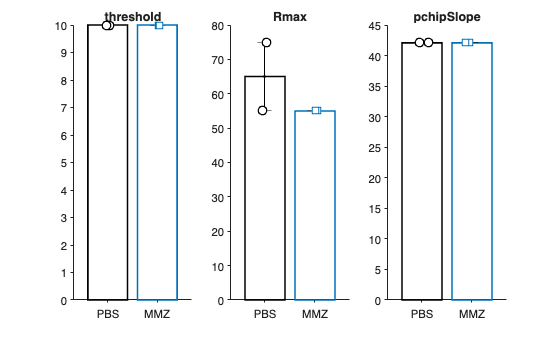

% --- (5) bar charts for threshold / Rmax / pchipSlope ---
figure('Color','w');

% horizontal jitter for datapoint (avoid overlapping of datapoint with similar values)
xJitter = 0.08;
ptSize = 40;


for p = 1:numel(varsParams)
    % 3 subplots, one for each parameter
    subplot(1,3,p); hold on; box off;
    
    % getting datapoint for each parameter of each treatment
    PBS_Parameter_datapoint = T2{T2.treatment=="PBS", varsParams(p)};
    MMZ_Parameter_datapoint = T2{T2.treatment=="MMZ", varsParams(p)};

    % getting parameter mean & SEM for each treatment
    PBS_ParameterMean = stats.PBS.meanPars(p); 
    PBS_ParameterSEM = stats.PBS.semPars(p);

    MMZ_ParameterMean = stats.MMZ.meanPars(p); 
    MMZ_ParameterSEM = stats.MMZ.semPars(p);

    % creating bar plot for each treatment
    b1 = bar(1, PBS_ParameterMean, 'FaceColor','none','EdgeColor','k','LineWidth',1.2);
    b2 = bar(2, MMZ_ParameterMean, 'FaceColor','none','EdgeColor',blue,'LineWidth',1.2);
    
    % adding error bars
    errorbar([1 2], [PBS_ParameterMean MMZ_ParameterMean], [PBS_ParameterSEM MMZ_ParameterSEM], 'k.', 'CapSize',10);

    % adding datapoints
    x1 = 1 + xJitter*randn(numel(PBS_Parameter_datapoint),1);
    scatter(x1, PBS_Parameter_datapoint, ptSize, 'o', ...
            'MarkerEdgeColor','k','MarkerFaceColor','w','LineWidth',1);
    
    x2 = 2 + xJitter*randn(numel(MMZ_Parameter_datapoint),1);
    scatter(x2, MMZ_Parameter_datapoint, ptSize, 's', ...
            'MarkerEdgeColor',blue,'MarkerFaceColor','w','LineWidth',1);

    % axis setting
    xlim([0.3 2.7]); xticks([1 2]); xticklabels({'PBS','MMZ'});
    title(varsParams{p});
    set(gca,'TickDir','out');
end


% === Outputs you can inspect ===
%CellCountTbl      % table of treatment vs CellCount
stats         % struct with mean/SD/SEM for spikes & parameters

stats = struct with fields:
    MMZ: [1×1 struct]
    PBS: [1×1 struct]


### Compare by experimenter & treatment

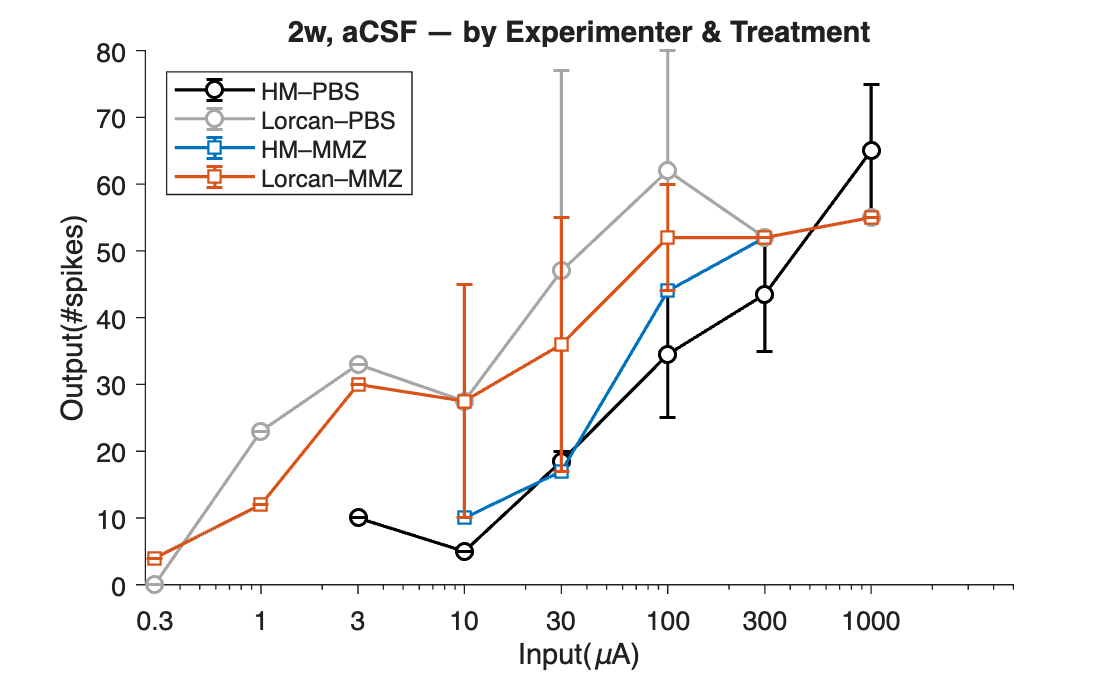

%% Compare by experimenter & treatment (HM vs Lorcan; PBS vs MMZ) at 2w, aCSF
fname = 'SummaryTable.xlsx';   % adjust path if needed
T = readtable(fname, 'FileType','spreadsheet');

% --- columns we need
needCols = {'Expter_Name','wpi','Expt_cond','treatment','CellID'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- FIXED FILTERS: 2w + aCSF ----
mask = strcmpi(T.wpi,"2w") & strcmpi(T.Expt_cond,"aCSF");
T = T(mask,:);

% sanity: repeated CellID within this subset?
ids = string(T.CellID);
[u,~,ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","pchipSlope"];
varsAll    = [varsSpikes varsParams];

for v = varsAll
    x = T.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T.(v) = reshape(x,[],1);
end

%% ---- build groups: experimenter + treatment ----
expNames  = ["HM","Lorcan"];           % add more if needed
treatList = ["PBS","MMZ"];             % circle vs square markers
T.treatment = string(T.treatment);

% Color palette
col.black = [0 0 0];
col.gray  = 0.65*[1 1 1];
col.blue  = [0 0.4470 0.7410];
col.red   = [0.85 0.325 0.098];

% mapping (experimenter x treatment) -> color & marker
styleMap = struct( ...
  'HM_PBS',     struct('C',col.black, 'M','o'), ...
  'Lorcan_PBS', struct('C',col.gray,  'M','o'), ...
  'HM_MMZ',     struct('C',col.blue,  'M','s'), ...
  'Lorcan_MMZ', struct('C',col.red,   'M','s') ...
);

% compute stats for each group
stats = struct();
for e = expNames
    for tr = treatList
        rows = (T.Expter_Name==e) & (T.treatment==tr);
        if ~any(rows), continue; end

        Xspk = T{rows, varsSpikes};
        mSpk = mean(Xspk, 1, 'omitnan');
        sdSpk = std(Xspk, 0, 1, 'omitnan');
        nSpk = sum(~isnan(Xspk), 1);
        semSpk = sdSpk ./ max(nSpk,1).^0.5;

        Xpar = T{rows, varsParams};
        mPar = mean(Xpar, 1, 'omitnan');
        sdPar = std(Xpar, 0, 1, 'omitnan');
        nPar = sum(~isnan(Xpar), 1);
        semPar = sdPar ./ max(nPar,1).^0.5;

        key = sprintf('%s_%s', e, tr);
        stats.(key).meanSpikes = mSpk;
        stats.(key).sdSpikes   = sdSpk;
        stats.(key).semSpikes  = semSpk;
        stats.(key).nSpikes    = nSpk;
        stats.(key).meanPars   = mPar;
        stats.(key).sdPars     = sdPar;
        stats.(key).semPars    = semPar;
        stats.(key).nPars      = nPar;
    end
end

%% ---- IO curves (mean ± SEM) ----
xVals = [0.3 1 3 10 30 100 300 1000];   % µA
figure('Color','w'); hold on;

plotOrder = {'HM_PBS','Lorcan_PBS','HM_MMZ','Lorcan_MMZ'};
legNames  = {'HM–PBS','Lorcan–PBS','HM–MMZ','Lorcan–MMZ'};

for i = 1:numel(plotOrder)
    k = plotOrder{i};
    if ~isfield(stats,k), continue; end
    st = stats.(k);
    sty = styleMap.(k);
    errorbar(xVals, st.meanSpikes, st.semSpikes, ...
        [sty.M '-'], 'Color', sty.C, 'MarkerFaceColor','w', ...
        'LineWidth',1.2,'CapSize',6);
end

set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input(\muA)'); ylabel('Output(#spikes)');
legend(legNames( ismember(plotOrder, fieldnames(stats)) ), 'Location','northwest');
title('2w, aCSF — by Experimenter & Treatment');

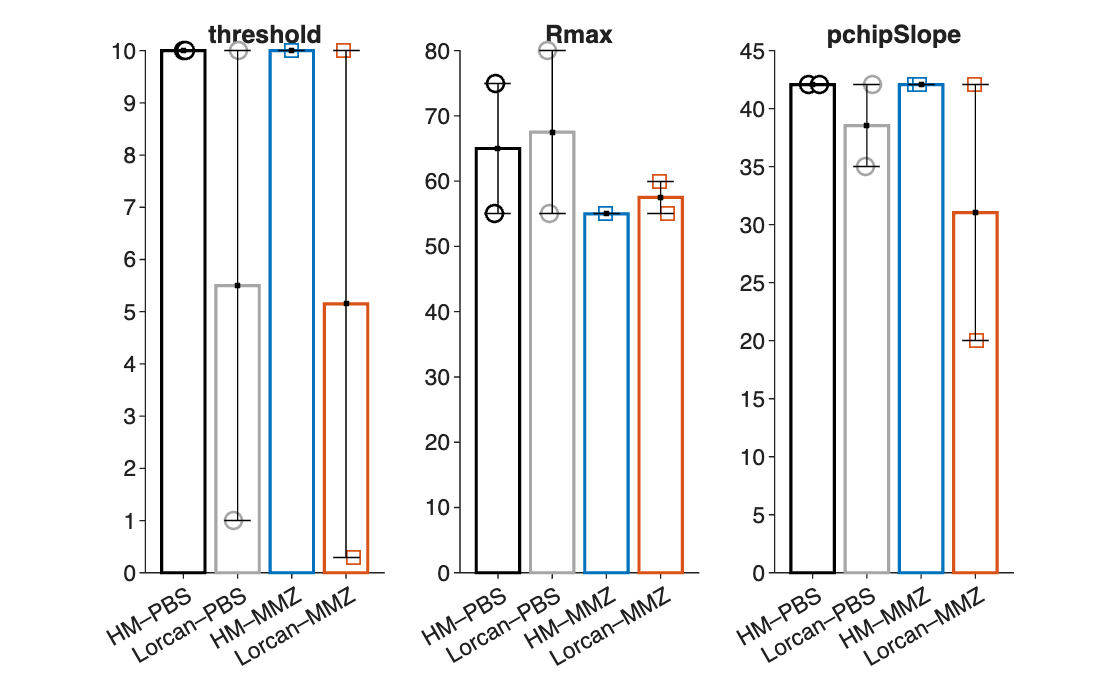


%% ---- Bar + points for threshold / Rmax / slope ----
figure('Color','w');

xJitter = 0.08;  ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    % x positions for the 4 groups
    xPos = [1 2 3 4];
    mu = nan(1,4); se = nan(1,4);

    for i = 1:numel(plotOrder)
        k = plotOrder{i};
        if ~isfield(stats,k), continue; end
        sty = styleMap.(k);
        mu(i) = stats.(k).meanPars(p);
        se(i) = stats.(k).semPars(p);

        % scatter raw datapoints
        parts = split(k,'_');    % {"HM","PBS"} or {"Lorcan","MMZ"}
        rows = (T.Expter_Name==parts(1)) & (T.treatment==parts(2));
        y = T{rows, varsParams(p)};

        scatter(xPos(i)+xJitter*randn(numel(y),1), y, ptSize, ...
            'Marker', sty.M, 'MarkerEdgeColor', sty.C, ...
            'MarkerFaceColor','w', 'LineWidth',1);
    end

    % bars
    for i = 1:numel(plotOrder)
        k = plotOrder{i};
        if ~isfield(stats,k), continue; end
        sty = styleMap.(k);
        bar(xPos(i), mu(i), 'FaceColor','none', 'EdgeColor', sty.C, 'LineWidth',1.2);
    end
    % error bars
    ebx = xPos( ismember(plotOrder, fieldnames(stats)) );
    ebu = mu( ismember(plotOrder, fieldnames(stats)) );
    ebe = se( ismember(plotOrder, fieldnames(stats)) );
    errorbar(ebx, ebu, ebe, 'k.', 'CapSize',10);

    xlim([0.3 4.7]); xticks(xPos);
    xticklabels({'HM–PBS','Lorcan–PBS','HM–MMZ','Lorcan–MMZ'});
    title(varsParams{p});
    set(gca,'TickDir','out');
end

### Compare by wpi & treatment

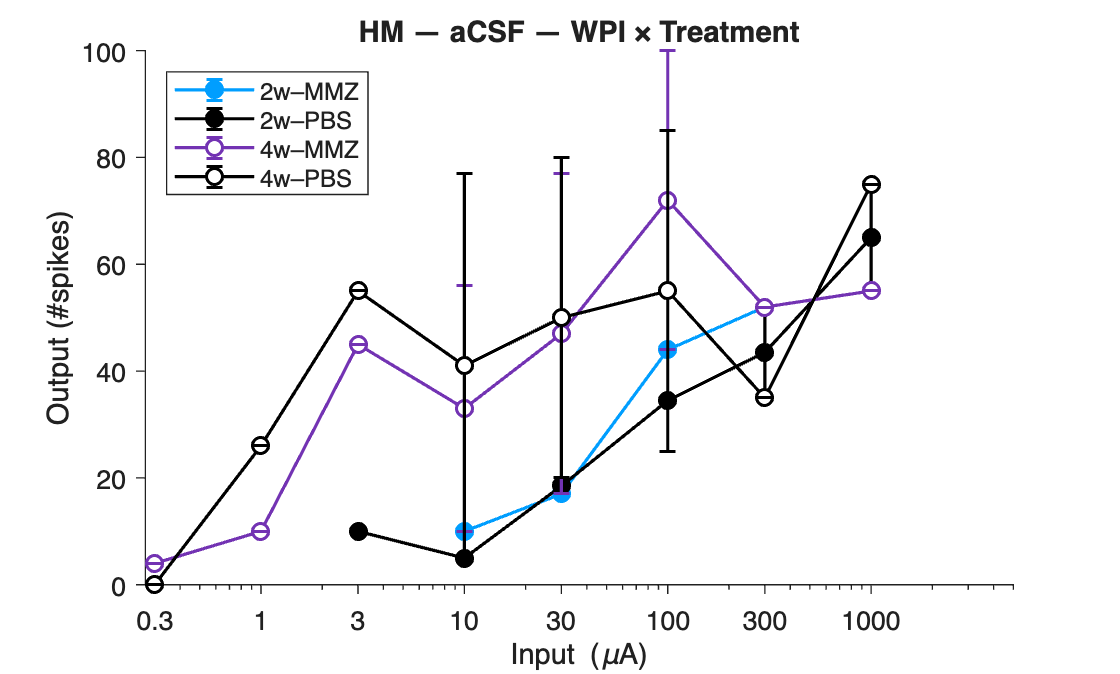

%% Compare by WPI (2w, 4w) & treatment (PBS, MMZ) for a chosen experimenter under aCSF
fname = 'SummaryTable.xlsx';   % adjust path if needed
T = readtable(fname, 'FileType','spreadsheet');

% --- columns we need
needCols = {'Expter_Name','wpi','Expt_cond','treatment','CellID'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- FIXED FILTERS you can change quickly ----
expFilter  = "HM";              % <--- set experimenter here
condFilter = "aCSF";            % <--- solution/condition

mask = strcmpi(T.Expter_Name,expFilter) & strcmpi(T.Expt_cond,condFilter) & ...
        (strcmpi(T.wpi,"2w") | strcmpi(T.wpi,"4w")) & ...
        (strcmpi(T.treatment,"PBS") | strcmpi(T.treatment,"MMZ"));
T = T(mask,:);

% sanity: repeated CellID within this subset?
ids = string(T.CellID);
[u,~,ic] = unique(ids,'stable');
counts = accumarray(ic,1);
dups = u(counts>1);
if ~isempty(dups)
    error('repeated cell: %s', strjoin(cellstr(dups), ', '));
end

%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","pchipSlope"];
varsAll    = [varsSpikes varsParams];

for v = varsAll
    x = T.(v);
    if isnumeric(x)
        x = double(x);
    elseif iscell(x)
        x = cellfun(@(y) str2double(string(y)), x);
    else
        x = str2double(string(x));
    end
    T.(v) = reshape(x,[],1);
end
T.treatment = string(T.treatment);
T.wpi       = string(T.wpi);

%% ---- build groups: WPI x treatment (within one experimenter) ----
wpis      = ["2w","4w"];
treatList = ["PBS","MMZ"];

%% --- COLORS / STYLES to match Fig. 2 ---
col.black  = [0 0 0];
col.blue   = [0 0.62 1.0];
col.purple = [0.45 0.20 0.70];

% helper: pick color by (wpi, treatment)
getColor = @(w,tr) ...
    (tr=="PBS"  & w=="2w") * col.black  + ...
    (tr=="PBS"  & w=="4w") * col.black   + ...
    (tr=="MMZ"  & w=="2w") * col.blue   + ...
    (tr=="MMZ"  & w=="4w") * col.purple;

% helper: filled for 2w, open for 4w
getFace  = @(w,tr,C) (w=="2w") .* C + (w=="4w") .* [1 1 1];

% compute stats for each group
stats = struct();
for w = wpis
    for tr = treatList
        rows = (T.wpi==w) & (T.treatment==tr);
        if ~any(rows), continue; end

        Xspk = T{rows, varsSpikes};
        mSpk = mean(Xspk, 1, 'omitnan');
        sdSpk = std(Xspk, 0, 1, 'omitnan');
        nSpk = sum(~isnan(Xspk), 1);
        semSpk = sdSpk ./ max(nSpk,1).^0.5;

        Xpar = T{rows, varsParams};
        mPar = mean(Xpar, 1, 'omitnan');
        sdPar = std(Xpar, 0, 1, 'omitnan');
        nPar  = sum(~isnan(Xpar), 1);
        semPar = sdPar ./ max(nPar,1).^0.5;

        key = sprintf('a%s_%s', w, tr);   % e.g., "2w_PBS"
        stats.(key).meanSpikes = mSpk;
        stats.(key).sdSpikes   = sdSpk;
        stats.(key).semSpikes  = semSpk;
        stats.(key).nSpikes    = nSpk;
        stats.(key).meanPars   = mPar;
        stats.(key).sdPars     = sdPar;
        stats.(key).semPars    = semPar;
        stats.(key).nPars      = nPar;
    end
end

%% ---- IO curves (mean ± SEM) ----
xVals = [0.3 1 3 10 30 100 300 1000];   % µA
figure('Color','w'); hold on;

% Order: 2w_MMZ, 2w_PBS, 4w_MMZ, 4w_PBS
plotOrder = {'a2w_MMZ','a2w_PBS','a4w_MMZ','a4w_PBS'};
legNames  = {'2w–MMZ','2w–PBS','4w–MMZ','4w–PBS'};

for i = 1:numel(plotOrder)
    k = plotOrder{i}; if ~isfield(stats,k), continue; end
    parts = split(k,'_');  w = erase(parts(1),"a");  tr = parts(2);
    C = getColor(w,tr);
    mFace = getFace(w,tr,C);  % filled for 2w, open for 4w
    errorbar(xVals, stats.(k).meanSpikes, stats.(k).semSpikes, ...
        'o-','Color',C,'MarkerEdgeColor',C,'MarkerFaceColor',mFace, ...
        'LineWidth',1.2,'CapSize',6);
end

set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input (\muA)'); ylabel('Output (#spikes)');
legend(legNames( ismember(plotOrder, fieldnames(stats)) ), 'Location','northwest');
title(sprintf('%s — %s — WPI × Treatment', expFilter, condFilter));

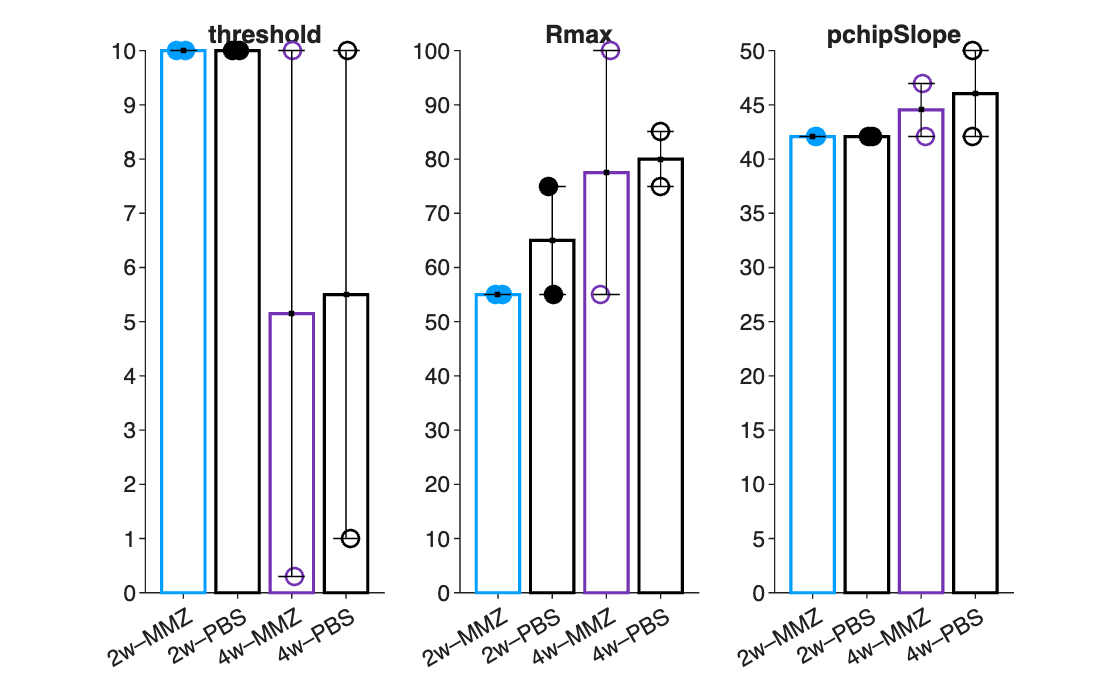


%% ---- Bar + points for threshold / Rmax / pchipSlope ----
figure('Color','w');
xJitter = 0.08;  ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    plotOrder = {'a2w_MMZ','a2w_PBS','a4w_MMZ','a4w_PBS'};
    xPos = 1:4;  mu = nan(1,4); se = nan(1,4);

    % points + means
    for i = 1:numel(plotOrder)
        k = plotOrder{i};
        if ~isfield(stats,k), continue; end
        parts = split(k,'_');              % {"w2w","MMZ"} etc.
        w  = erase(parts(1),"a");          % "2w" or "4w"
        tr = parts(2);

        % color & face per Fig. 2
        C     = getColor(w,tr);
        mFace = getFace(w,tr,C);

        mu(i) = stats.(k).meanPars(p);
        se(i) = stats.(k).semPars(p);

        % raw datapoints
        rows = (T.wpi==w) & (T.treatment==tr);
        y = T{rows, varsParams(p)};
        scatter(xPos(i)+xJitter*randn(numel(y),1), y, ptSize, ...
            'Marker','o','MarkerEdgeColor',C,'MarkerFaceColor',mFace,'LineWidth',1);
    end

    % bars (edge color only) + SEM
    for i = 1:numel(plotOrder)
        k = plotOrder{i};
        if ~isfield(stats,k), continue; end
        parts = split(k,'_');  w = erase(parts(1),"a");  tr = parts(2);
        C = getColor(w,tr);
        bar(xPos(i), mu(i), 'FaceColor','none','EdgeColor',C,'LineWidth',1.2);
    end
    good = ~isnan(mu);
    errorbar(xPos(good), mu(good), se(good), 'k.', 'CapSize',10);

    xlim([0.3 4.7]); xticks(xPos);
    xticklabels({'2w–MMZ','2w–PBS','4w–MMZ','4w–PBS'});
    title(varsParams{p});
    set(gca,'TickDir','out');
end

### Compare by experimental conditions

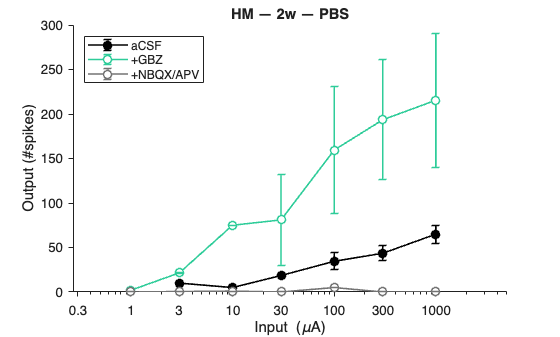

%% Compare by experimental bath condition for a chosen experimenter at 2w
fname = 'SummaryTable.xlsx';
T = readtable(fname, 'FileType','spreadsheet');

% --- required columns
needCols = {'Expter_Name','wpi','treatment','Expt_cond','CellID'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- QUICK FILTERS ----
expFilter     = "HM";          % who ran it
wpiFilter     = "2w";
treatFilter   = "PBS";         % 'PBS' (8/11) or 'MMZ' (9/12)
condsToCompare = ["aCSF","GBZ","NBQX_APV"];        % 8/9
% condsToCompare = ["aCSF","GBZ","NBQX_APV"];  % 11/12 (3-way)

% accept both "NBQX_APV" and "NBQX+APV" labels in the sheet
isNBQX = @(s) strcmpi(s,"NBQX_APV") | strcmpi(s,"NBQX+APV");

mask = strcmpi(T.Expter_Name,expFilter) & strcmpi(T.wpi,wpiFilter) & ...
       strcmpi(T.treatment,treatFilter) & ...
       ( strcmpi(T.Expt_cond,"aCSF") | strcmpi(T.Expt_cond,"GBZ") | isNBQX(T.Expt_cond) );
T = T(mask,:);

%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","pchipSlope"];
for v = [varsSpikes varsParams]
    x = T.(v);  if ~isnumeric(x), x = str2double(string(x)); end
    T.(v) = reshape(double(x),[],1);
end
T.Expt_cond = string(T.Expt_cond);
% normalize NBQX label
T.Expt_cond(isNBQX(T.Expt_cond)) = "NBQX_APV";

%% ---- COLORS & HELPERS (replace your getStyle block with this) ----
col.black  = [0 0 0];                  % PBS aCSF (Ctrl)
col.mint   = [0.18 0.80 0.60];         % PBS +GBZ
col.blue   = [0 0.62 1.00];            % MMZ aCSF (Ctrl)
col.orange = [0.98 0.60 0.20];         % MMZ +GBZ
col.gray   = 0.45*[1 1 1];             % PBS +NBQX_APV
col.purple = [0.35 0.25 0.80];         % MMZ +NBQX_APV (darker purple)

% line/edge color by (treatment, condition)
getColor = @(treat,cond) ...
    (treat=="PBS" & cond=="aCSF")    * col.black  + ...
    (treat=="PBS" & cond=="GBZ")     * col.mint   + ...
    (treat=="PBS" & cond=="NBQX_APV")* col.gray   + ...
    (treat=="MMZ" & cond=="aCSF")    * col.blue   + ...
    (treat=="MMZ" & cond=="GBZ")     * col.orange + ...
    (treat=="MMZ" & cond=="NBQX_APV")* col.purple;

% marker face: aCSF = filled (same color); drug baths = open (white)
getFace  = @(treat,cond) (cond=="aCSF").*getColor(treat,cond) + (cond~="aCSF").*[1 1 1];

%% ---- compute stats per bath condition ----
stats = struct();
for c = condsToCompare
    rows = (T.Expt_cond==c);
    if ~any(rows), continue; end
    Xspk = T{rows, varsSpikes};
    Xpar = T{rows, varsParams};
    mSpk = mean(Xspk,1,'omitnan'); sdSpk = std(Xspk,0,1,'omitnan');
    nSpk = sum(~isnan(Xspk),1);    semSpk = sdSpk./sqrt(max(nSpk,1));
    mPar = mean(Xpar,1,'omitnan'); sdPar = std(Xpar,0,1,'omitnan');
    nPar = sum(~isnan(Xpar),1);    semPar = sdPar./sqrt(max(nPar,1));
    key = char(c);
    stats.(key).meanSpikes = mSpk; stats.(key).semSpikes = semSpk;
    stats.(key).meanPars   = mPar; stats.(key).semPars   = semPar;
end

%% ---- IO curves ----
xVals = [0.3 1 3 10 30 100 300 1000];
figure('Color','w'); hold on;

% plot order & legend text that match your figure
order = cellstr(condsToCompare);
legTxt = replace(order, "NBQX_APV","+NBQX/APV");
legTxt(strcmpi(order,"aCSF")) = {"aCSF"};
legTxt(strcmpi(order,"GBZ"))  = {"+GBZ"};

for i = 1:numel(order)
    k = order{i}; if ~isfield(stats,k), continue; end
    styC    = getColor(treatFilter, string(k));
    styFace = getFace (treatFilter, string(k));
    
    errorbar(xVals, stats.(k).meanSpikes, stats.(k).semSpikes, ...
        'o-','Color',styC,'MarkerEdgeColor',styC,'MarkerFaceColor',styFace, ...
        'LineWidth',1.2,'CapSize',6);
end
set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input (\muA)'); ylabel('Output (#spikes)');
title(sprintf('%s — %s — %s', expFilter, wpiFilter, treatFilter));
legend(legTxt,'Location','northwest');

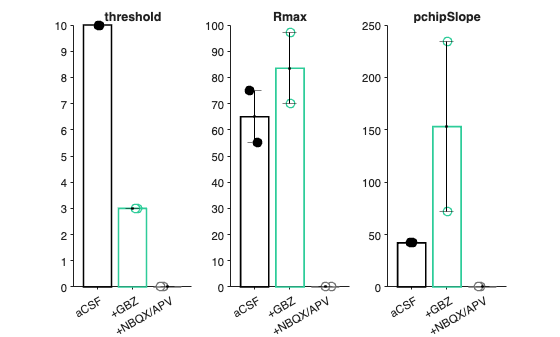


%% ---- Bar + points for threshold / Rmax / pchipSlope ----
figure('Color','w'); xJitter = 0.08; ptSize = 40;
for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;
    xPos = 1:numel(order); mu = nan(1,numel(order)); se = nan(1,numel(order));
    for i = 1:numel(order)
        k = order{i}; if ~isfield(stats,k), continue; end
        mu(i) = stats.(k).meanPars(p); se(i) = stats.(k).semPars(p);
        rows = (T.Expt_cond==string(k));
        sty  = getStyle(treatFilter, string(k));
        y = T{rows, varsParams(p)};
        styC    = getColor(treatFilter, string(k));
        styFace = getFace (treatFilter, string(k));
        
        % raw datapoints
        y = T{rows, varsParams(p)};
        scatter(xPos(i)+xJitter*randn(numel(y),1), y, ptSize, ...
            'Marker','o','MarkerEdgeColor',styC,'MarkerFaceColor',styFace,'LineWidth',1);

        % bar (set properties after creation)
        b = bar(xPos(i), mu(i));
        b.FaceColor = 'none';
        b.EdgeColor = styC;
        b.LineWidth = 1.2;
    end
    good = ~isnan(mu);
    errorbar(xPos(good), mu(good), se(good), 'k.', 'CapSize',10);
    xlim([0.3 numel(order)+0.7]); xticks(1:numel(order)); xticklabels(legTxt);
    title(varsParams{p}); set(gca,'TickDir','out');
end

### Compare by experimental condition & Treatment

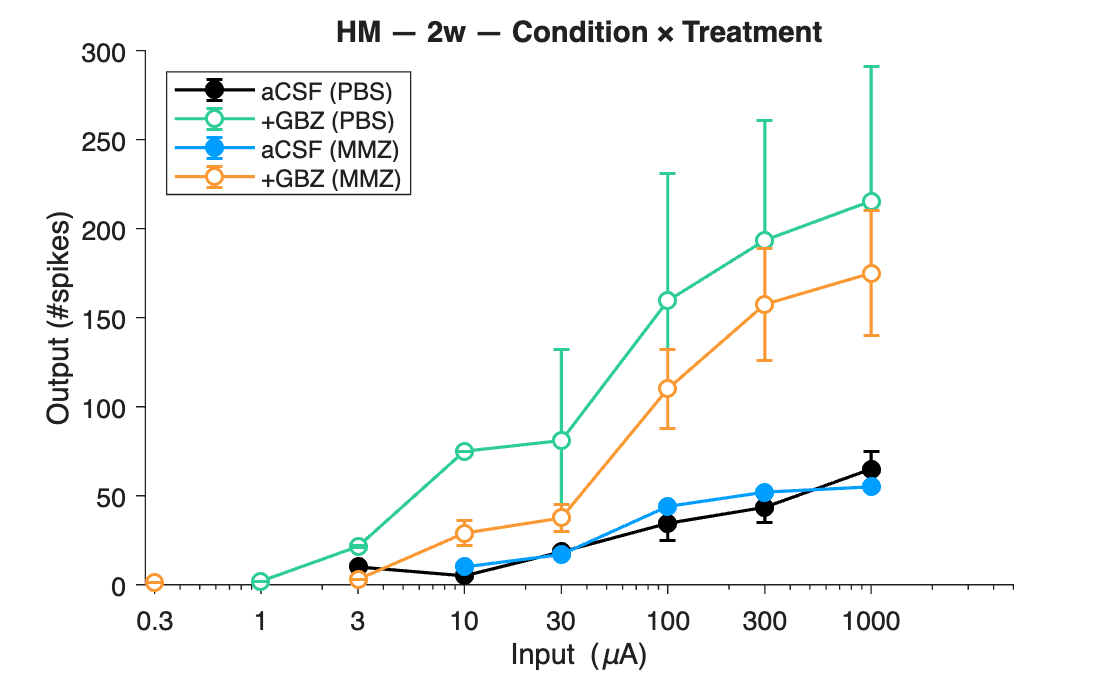

%% Compare by experimental condition & treatment at 2w for a chosen experimenter
fname = 'SummaryTable.xlsx';
T = readtable(fname, 'FileType','spreadsheet');

% --- required columns
needCols = {'Expter_Name','wpi','treatment','Expt_cond','CellID'};
for k = 1:numel(needCols)
    assert(ismember(needCols{k}, T.Properties.VariableNames), ...
        'Missing column: %s', needCols{k});
    T.(needCols{k}) = strtrim(string(T.(needCols{k})));
end

%% ---- filters ----
expFilter = "HM";     % experimenter
wpiFilter = "2w";     % fixed to 2w for this comparison

mask = strcmpi(T.Expter_Name,expFilter) & strcmpi(T.wpi,wpiFilter) & ...
       (strcmpi(T.treatment,"PBS") | strcmpi(T.treatment,"MMZ")) & ...
       (strcmpi(T.Expt_cond,"aCSF") | strcmpi(T.Expt_cond,"GBZ"));
T = T(mask,:);


%% ---- numeric columns ----
varsSpikes = ["I_0_3","I_1","I_3","I_10","I_30","I_100","I_300","I_1000"];
varsParams = ["threshold","Rmax","pchipSlope"];
for v = [varsSpikes varsParams]
    x = T.(v); if ~isnumeric(x), x = str2double(string(x)); end
    T.(v) = reshape(double(x),[],1);
end
T.treatment = string(T.treatment);
T.Expt_cond = string(T.Expt_cond);

%% ---- color/style map (matches your figure) ----
col.black  = [0 0 0];          % PBS aCSF
col.blue   = [0 0.62 1.00];    % MMZ aCSF
col.mint   = [0.18 0.80 0.60]; % PBS +GBZ
col.orange = [0.98 0.60 0.20]; % MMZ +GBZ

styleMap = struct( ...
  'PBS_aCSF', struct('C',col.black,  'Face',col.black ), ...  % filled
  'MMZ_aCSF', struct('C',col.blue,   'Face',col.blue  ), ...  % filled
  'PBS_GBZ',  struct('C',col.mint,   'Face',[1 1 1]   ), ...  % open
  'MMZ_GBZ',  struct('C',col.orange, 'Face',[1 1 1]   ) ...  % open
);

%% ---- compute stats for each (treatment, condition) pair ----
pairs = {'PBS_aCSF','MMZ_aCSF','PBS_GBZ','MMZ_GBZ'}; % master list
stats = struct();

for i = 1:numel(pairs)
    pc = split(pairs{i},'_');  tr = pc(1);  cond = pc(2);
    rows = (T.treatment==tr) & (T.Expt_cond==cond);
    if ~any(rows), continue; end
    Xspk = T{rows, varsSpikes};
    Xpar = T{rows, varsParams};

    mSpk = mean(Xspk,1,'omitnan'); sdSpk = std(Xspk,0,1,'omitnan');
    nSpk = sum(~isnan(Xspk),1);     semSpk = sdSpk ./ sqrt(max(nSpk,1));

    mPar = mean(Xpar,1,'omitnan'); sdPar = std(Xpar,0,1,'omitnan');
    nPar = sum(~isnan(Xpar),1);     semPar = sdPar ./ sqrt(max(nPar,1));

    stats.(pairs{i}).meanSpikes = mSpk;
    stats.(pairs{i}).semSpikes  = semSpk;
    stats.(pairs{i}).meanPars   = mPar;
    stats.(pairs{i}).semPars    = semPar;
end

%% ---- IO curves ----
xVals = [0.3 1 3 10 30 100 300 1000];
figure('Color','w'); hold on;

plotOrder = {'PBS_aCSF','PBS_GBZ','MMZ_aCSF','MMZ_GBZ'};
legNames  = {'aCSF (PBS)','+GBZ (PBS)','aCSF (MMZ)','+GBZ (MMZ)'};

for i = 1:numel(plotOrder)
    k = plotOrder{i}; if ~isfield(stats,k), continue; end
    st = stats.(k); stl = styleMap.(k);
    errorbar(xVals, st.meanSpikes, st.semSpikes, ...
        'o-','Color',stl.C,'MarkerEdgeColor',stl.C,'MarkerFaceColor',stl.Face, ...
        'LineWidth',1.2,'CapSize',6);
end
set(gca,'XScale','log','Box','off','TickDir','out');
xticks(xVals); xlim([min(xVals)*0.9, max(xVals)*5]);
xlabel('Input (\muA)'); ylabel('Output (#spikes)');
legend(legNames( ismember(plotOrder, fieldnames(stats)) ), 'Location','northwest');
title(sprintf('%s — %s — Condition × Treatment', expFilter, wpiFilter));

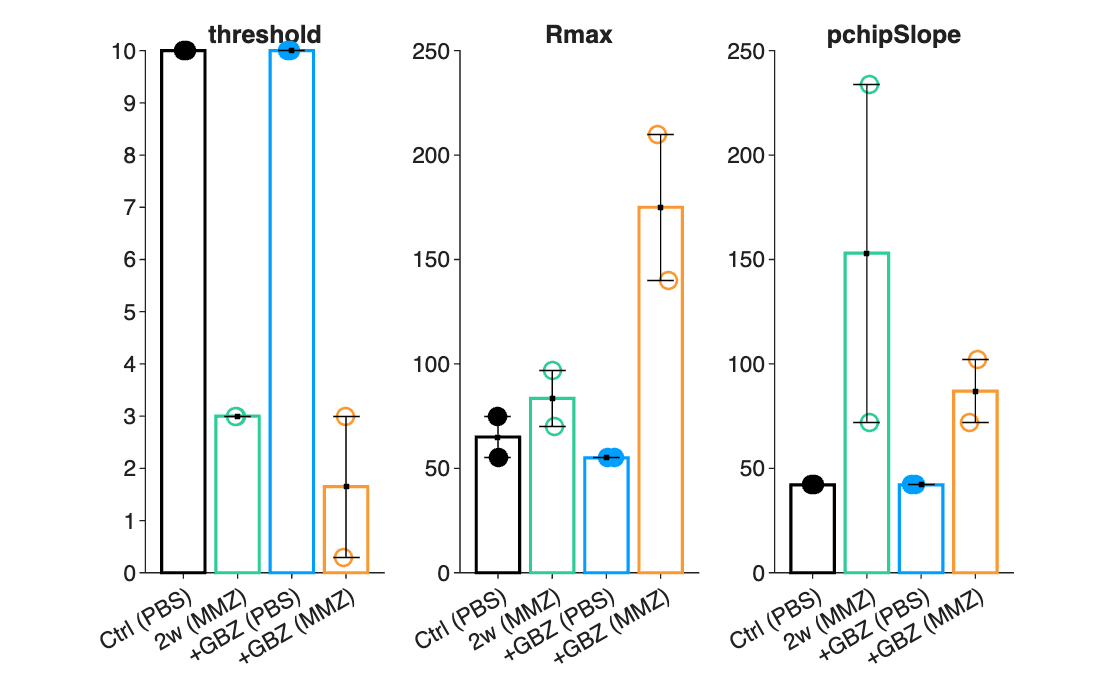


%% ---- Bar + points for threshold / Rmax / pchipSlope ----
figure('Color','w'); xJitter = 0.08; ptSize = 40;

for p = 1:numel(varsParams)
    subplot(1,3,p); hold on; box off;

    xPos = 1:numel(plotOrder); mu = nan(1,numel(plotOrder)); se = nan(1,numel(plotOrder));
    for i = 1:numel(plotOrder)
        k = plotOrder{i}; if ~isfield(stats,k), continue; end
        mu(i) = stats.(k).meanPars(p);
        se(i) = stats.(k).semPars(p);

        pc = split(k,'_'); tr = pc(1); cond = pc(2);
        rows = (T.treatment==tr) & (T.Expt_cond==cond);
        y = T{rows, varsParams(p)};
        stl = styleMap.(k);

        scatter(xPos(i)+xJitter*randn(numel(y),1), y, ptSize, ...
            'Marker','o','MarkerEdgeColor',stl.C,'MarkerFaceColor',stl.Face,'LineWidth',1);
        bar(xPos(i), mu(i), 'FaceColor','none','EdgeColor',stl.C,'LineWidth',1.2);
    end
    good = ~isnan(mu);
    errorbar(xPos(good), mu(good), se(good), 'k.', 'CapSize',10);

    xlim([0.3 numel(plotOrder)+0.7]); xticks(xPos);
    xticklabels({'Ctrl (PBS)','2w (MMZ)','+GBZ (PBS)','+GBZ (MMZ)'});
    title(varsParams{p}); set(gca,'TickDir','out');
end